# Introducing iset3d calculations

Rendera the sphere scene to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 1 textures.
***Scene parsed.


The recipe has many fields that control the properties of the scene and how it is rendered.  We simply list them here.  A lot of the tutorial concerns how to set and get properties from the many slots in an ISET3d recipe.

thisR

thisR =   recipe with properties:

            camera: [1×1 struct]
           sampler: [1×1 struct]
              film: [1×1 struct]
            filter: []
        integrator: [1×1 struct]
          renderer: []
            lookAt: [1×1 struct]
             scale: [0×3 double]
             world: {5×1 cell}
            lights: {1×0 cell}
    transformTimes: []
         inputFile: '/Users/wandell/Documents/MATLAB/iset3d/data/V3/sphere/sphere.pbrt'
        outputFile: '/Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt'
      renderedFile: ''
           version: 3
         materials: [1×1 struct]
          textures: [1×1 struct]
            assets: [1×1 tree]
          exporter: 'C4D'
             media: []
          metadata: []
         recipeVer: 2
           verbose: 2


## Edit the recipe

Add a point light, needed by this scene.

pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light','add',pointLight);

There are many different parameters that can be set. This is the just an introductory script, so we do a minimal number of parameters. Much of what is described in other scripts expands on this section.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Write the recipe, render it, and show it

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt


There is no lens, just a pinhole.  In that case, we are rendering a scene. If we had a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

Docker container vistalab/pbrt-v3-spectral:latest
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere_depth.pbrt
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere.dat /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
*** Rendering time for sphere:  14.1 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere_depth.dat /Users/wande

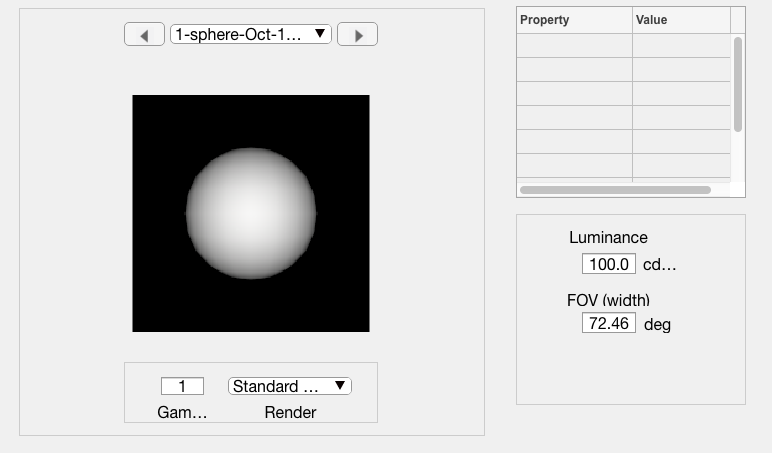

sceneWindow(scene);

## By default, we also computed the depth map

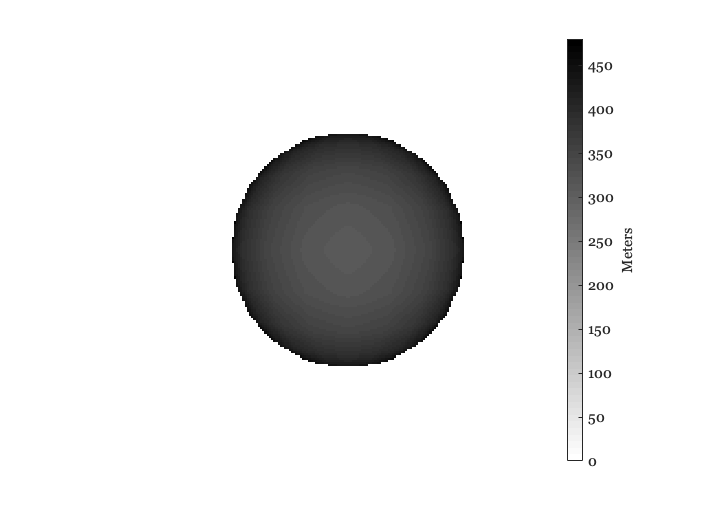

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can also try a different light, which is more blue and distant 

distantLight = piLightCreate('distant','type','distant',  'spd', [9000 0.001],  'cameracoordinate', true);
thisR.set('light','delete',pointLight.name);
thisR.set('light','add',distantLight);

This is a faster way to Write Render and Show

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/sphere" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/sphere":"/Users/wandell/Documents/MATLAB/iset3d/local/sphere" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/sphere/renderings/sphere.dat /Users/wandell/Documents/MATLAB/iset3d/local/sphere/sphere.pbrt
*** Rendering time for sphere:  13.7 sec ***

  Reading image h=192 x w=192 x 31 spectral planes.


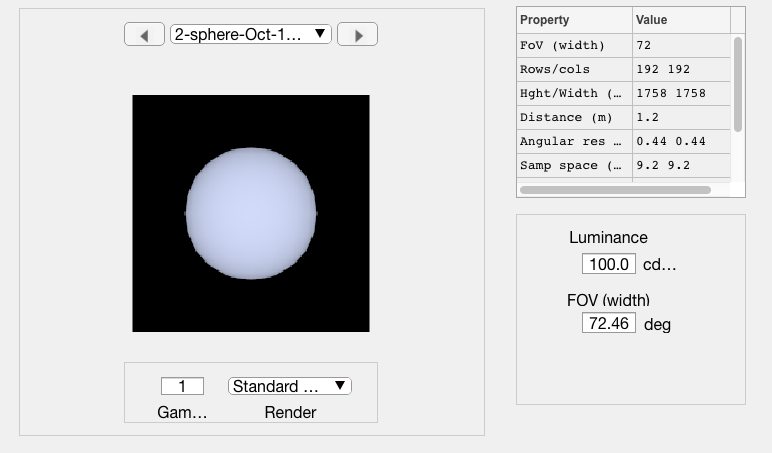

piWRS(thisR);